# MECH 1208 - Week 3 Deliverable

Author: Jonas Wagner

Date: 2022-01-13

## Method within Instructions

clear
close all

% Setup Stuff
w_in = 500;
min2sec = 60;
in2ft = 1/12;


% Arrangment 1
PD_p_1 = 1;
PD_g_1 = 2;

% Arrangment 2
PD_p_2 = 1.5;
PD_g_2 = 1.5;

% Arrangment 3
PD_p_3 = 2;
PD_g_3 = 1;

% 1)
d_1 = (PD_p_1 + PD_g_1) / 2

d_1 = 1.5000

d_2 = (PD_p_2 + PD_g_2) / 2

d_2 = 1.5000

d_3 = (PD_p_3 + PD_g_3) / 2

d_3 = 1.5000


% 2)
v_1 = w_in * (pi * PD_p_1) * min2sec * in2ft

v_1 = 7.8540e+03

v_2 = w_in * (pi * PD_p_2) * min2sec * in2ft

v_2 = 1.1781e+04

v_3 = w_in * (pi * PD_p_3) * min2sec * in2ft

v_3 = 1.5708e+04


% 3)
w_1 = v_1 / (pi * PD_g_1) / min2sec / in2ft

w_1 = 250.0000

w_2 = v_2 / (pi * PD_g_2) / min2sec / in2ft

w_2 = 500

w_3 = v_3 / (pi * PD_g_3) / min2sec / in2ft

w_3 = 1.0000e+03

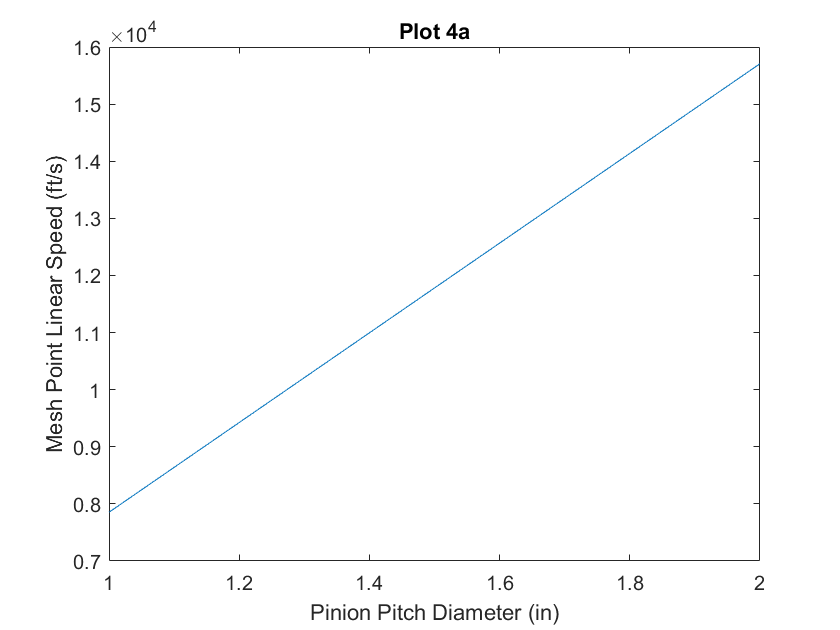


% 4)
PD_pinion = linspace(1,2);
V = w_in * pi * PD_pinion * min2sec * in2ft;
W = V ./ (pi * (3 - PD_pinion)) / min2sec / in2ft;
ratio = W ./ w_in;

% 4a)
figure()
plot(PD_pinion, V)
title('Plot 4a')
xlabel('Pinion Pitch Diameter (in)')
ylabel('Mesh Point Linear Speed (ft/s)')

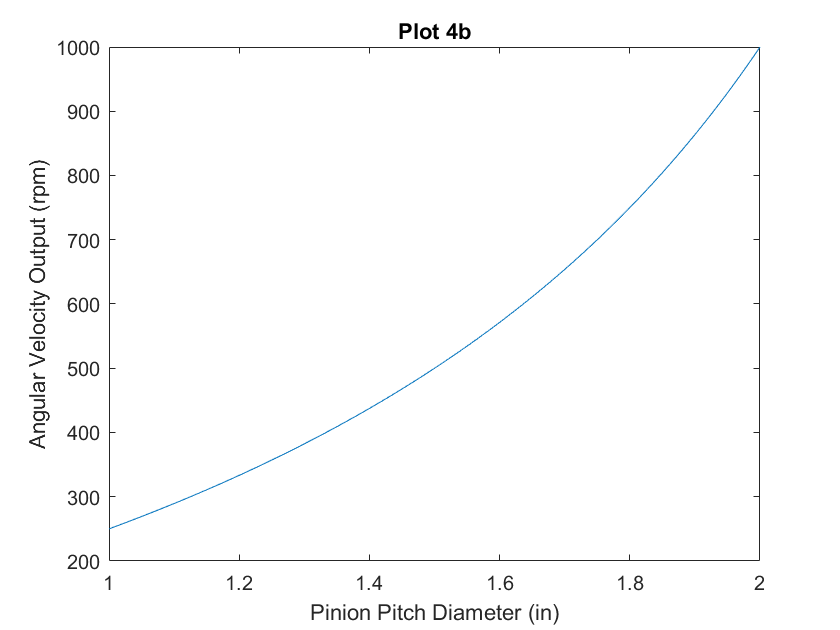


% 4b)
figure()
plot(PD_pinion, W)
title('Plot 4b')
xlabel('Pinion Pitch Diameter (in)')
ylabel('Angular Velocity Output (rpm)')

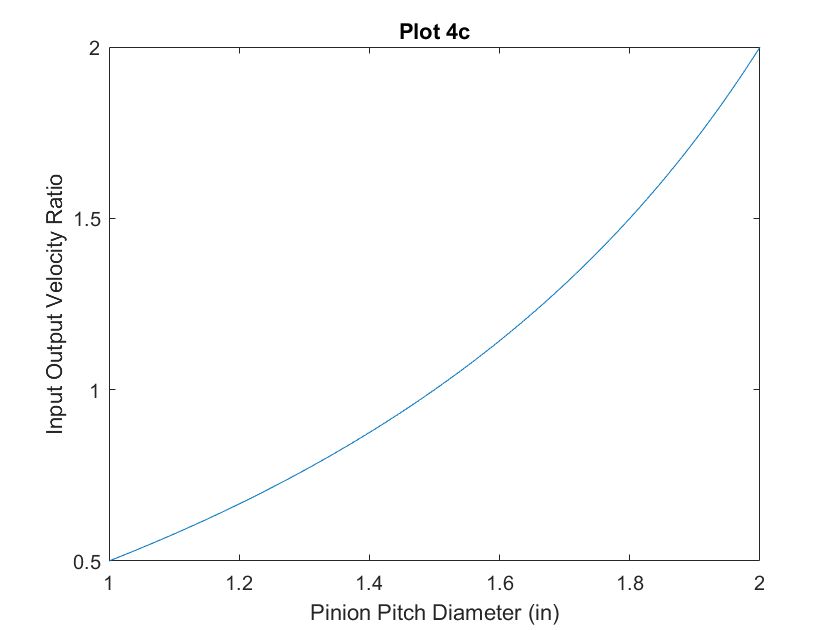


% 4c)
figure()
plot(PD_pinion, W ./ w_in)
title('Plot 4c')
xlabel('Pinion Pitch Diameter (in)')
ylabel('Input Output Velocity Ratio')

## My Standard Approach

clear
close all

% Input RPM
w_in = 500;

% Unit Conversions
min2sec = 60;
in2ft = 1/12;

% Mesh Velocity: v = rpm2rad/s (= 2 pi) * radius (= diameter /2) * unit conversiosn
meshVel = @(w_in, DP_p) w_in .* pi .* DP_p .* min2sec .* in2ft

meshVel = function_handle with value:
    @(w_in,DP_p)w_in.*pi.*DP_p.*min2sec.*in2ft



% Output RPM
outRPM = @(w_in, DP_p, DP_g) w_in * (DP_p ./ DP_g)

outRPM = function_handle with value:
    @(w_in,DP_p,DP_g)w_in*(DP_p./DP_g)



% Gear Ratio
gearRatio = @(DP_p, DP_g) DP_p ./ DP_g

gearRatio = function_handle with value:
    @(DP_p,DP_g)DP_p./DP_g



% Arangments
DP_p = [1, 1.5, 2]'

DP_p =     1.0000
    1.5000
    2.0000


DP_g = [2, 1.5, 1]'

DP_g =     2.0000
    1.5000
    1.0000



% 1)
D = (DP_p + DP_g);
d_1 = D(1)

d_1 = 3

d_2 = D(2)

d_2 = 3

d_3 = D(3)

d_3 = 3


% 2)
V = meshVel(w_in, DP_p)

V = 	1.0e+04 *

    0.7854
    1.1781
    1.5708


v_1 = V(1)

v_1 = 7.8540e+03

v_2 = V(2)

v_2 = 1.1781e+04

v_3 = V(3)

v_3 = 1.5708e+04


% 3)
W = outRPM(w_in, DP_p, DP_g)

W =          250
         500
        1000


w_1 = W(1)

w_1 = 250

w_2 = W(2)

w_2 = 500

w_3 = W(3)

w_3 = 1000


% 4)
DP_p = 1:0.1:2;

% Ploting
figure()
sgtitle('Week 3 Deliverable Plots')
axes(1) = subplot(3,1,1)

axes =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


plot(DP_p, meshVel(w_in, DP_p))
ylabel('Mesh Velocity (ft/s)')

axes(2) = subplot(3,1,2)

axes =   1×2 Axes array:

    Axes    Axes


plot(DP_p, outRPM(w_in, DP_p, 3 - DP_p))
ylabel('Output Angular Velocity (rpm)')

axes(3) = subplot(3,1,3)

axes =   1×3 Axes array:

    Axes    Axes    Axes


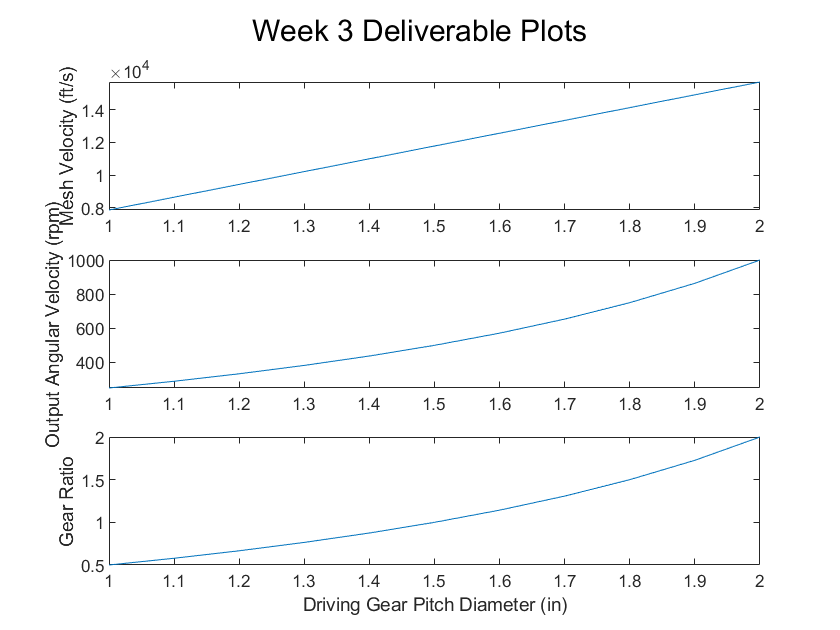

plot(DP_p, gearRatio(DP_p, 3 - DP_p))
ylabel('Gear Ratio')
xlabel('Driving Gear Pitch Diameter (in)')

linkaxes(axes, 'x')